# Speech-to-Text Using 3rd-Party Speech APIs

This example shows how to perform speech-to-text transcription in MATLAB® using 3rd-party cloud-based APIs.

## Introduction

The [`speech2text`](https://www.mathworks.com/help/audio/ref/speech2text.html) function provides the ability to use 3rd-party speech APIs to perform speech-to-text transcription. The function supports the following 3rd party tools:

- [Google™ Cloud Speech-to-Text](https://cloud.google.com/speech-to-text/)

- [IBM™ Watson Speech to Text](https://www.ibm.com/watson/services/speech-to-text/)

- [Microsoft™ Azure Speech Services](https://azure.microsoft.com/en-us/services/cognitive-services/speech-to-text/)

- [Amazon™ Transcribe](https://aws.amazon.com/transcribe/)

To use the `speech2text` function with cloud-based APIs, you must have the following products installed:

- MATLAB release R2018a or later

- Audio Toolbox™

## Set Up 3rd Party API

Before you start using the `speech2text` function, you need to set up the API. 

First, run the `setup.m` script from the downloaded `speech2text` folder. This makes sure the downloaded files are added to your MATLAB path.

Next, create an account with the cloud service and generate an authorization key. Google, IBM, Microsoft, and Amazon APIs have different requirements to set up an account and generate an authorization key.

### Google

Using the Google Cloud Speech-to-Text API requires an API key for authorizing the request. The following steps describe how to create the API key. This is also described in the [Google documentation](https://cloud.google.com/docs/authentication/api-keys):

1. Navigate to the [APIs & Services->Credentials](https://console.cloud.google.com/apis/credentials) panel in Cloud Platform Console.

2. Select **Create credentials**, then select **API key** from the drop-down menu. 

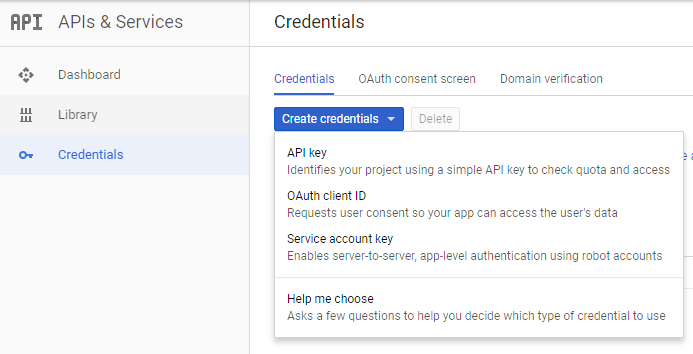

3. Click the **Create** button. A dialog box appears which displays your newly created key.

4. Once you have the API key, download it and create a JSON file such that:

    a. JSON file should have an attribute called: "key" (case sensitive). For example, if the API key generated is ABCDefgh, then the file will have the attribute "key", and value "ABCDefgh", as shown below:

    

    b. Optionally you can specify the "recongnizeUrl" (case sensitive) attribute. If you don't specify this, the recognizeUrl defaults to `https://speech.googleapis.com/v1/speech:recognize`

    c. Save the file as "Google_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "Google_Credentials_Speech2text.json" to obtain the API key, which the Google Speech API requires for authentication.

### IBM

IBM Speech to Text API is offered through IBM Cloud services which now uses token-based Identity and Access Management (IAM) authentication. To begin, you must create an IBM Cloud account, a Speech to Text service instance, and go to the service dashboard and copy your credentials - API Key and URL values.

This information is also described in the  [IBM Speech to Text documentation](https://console.bluemix.net/docs/services/speech-to-text/getting-started.html#gettingStarted):

1. Go to the [Speech to Text service](https://console.bluemix.net/catalog/services/speech-to-text/) and sign up for a free IBM Cloud account or log in to your existing account.

2. After you log in, enter speech-to-text-tutorial in the Service name field of the Speech to Text page. Click **Create**.

3. Copy the credentials created:

    a. Go to the [IBM Cloud dashboard](https://console.bluemix.net/dashboard/apps)

    b. Select the Speech to Text service instance.

    c. Click **Show Credentials" under *Manage**.

    d. Copy the API Key and URL values.

4. Write the API Key and URL values to a JSON file:

    a. For example, if the API Key generated is "abcd-1234-WXYZ" and the URL is "https://stream.watsonplatform.net/speech-to-text/api" then the JSON file will have the attribute "apikey" with value "abcd-1234-WXYZ" and "url" with value "https://stream.watsonplatform.net/speech-to-text/api", as shown below. In some cases, speech2text doesn't work if the URL is not the same as the one below. If you encounter this problem, try using the URL below and not the one shown in your IBM Cloud dashboard.

    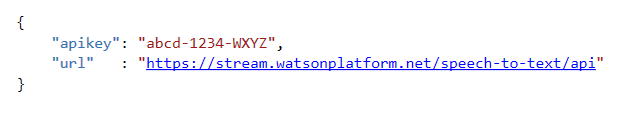

    b. Save the file as "IBM_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "IBM_Credentials_Speech2text.json" to obtain the API Key and URL.

### Microsoft

Microsoft's Speech to Text API is part of Microsoft Azure Speech Services, and requires subscription keys. You can obtain the keys from the Cognitive Services subscription page by following the steps below. This information is also described in [Microsoft Speech Service Documentation](https://docs.microsoft.com/en-us/azure/cognitive-services/speech-service/get-started):

1. Go to the Cognitive Services subscription, and login/create your Microsoft Azure account.

2. Select Speech Services and click on **Get API Key**.

3. This returns a primary and secondary key – "Key 1" and "Key 2". Select your location/country and get the endpoint URI. Copy these to create a JSON file:

    a. JSON file should have four attributes: "key1", "key2", "tokenUri" and "requestUri" (case sensitive). The URIs can also be obtained from [Speech Service REST APIs documentation](https://docs.microsoft.com/en-us/azure/cognitive-services/Speech-Service/rest-apis). For example, if the Key 1 generated is abcd1235 and Key 2 is 5678wxyz then the JSON file will have the attribute "key1" with value "abcd1235" and "key2" with value "5678wxyz" and the URIs as shown below:

    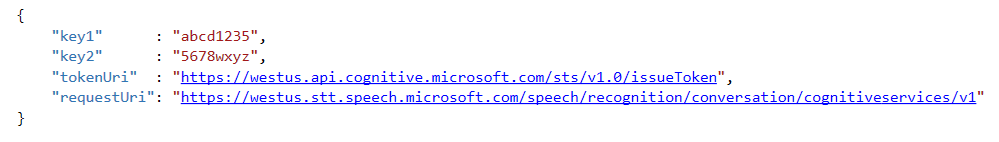

    b. Save the file as "Microsoft_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "Microsoft_Credentials_Speech2text.json" to obtain the subscription key.

### Amazon

To use Amazon Transcribe, you must set up an AWS account, download an access key, and install and configure the AWS Command Line Interface on your computer. These prerequisites are described in [Getting started with the AWS CLI](https://docs.aws.amazon.com/cli/latest/userguide/cli-chap-getting-started.html).

## Transcribe Speech Signal

Read an audio file and get the audio samples (`y`) and sampling frequency (`fs`).

[y,fs] = audioread('speech_dft.mp3');

To transcribe a speech signal:

- Create a [`speechClient`](https://www.mathworks.com/help/audio/ref/speechclient.html) object for the desired speech API. All cloud-based speech client options have a name property and a timeout property. The timeout property is the default connection timeout used when communicating with the server. The Amazon speech client has additional options to control how the text returned from the server is segmented and whether it contains time stamps.

- Call the [`speech2text`](https://www.mathworks.com/help/audio/ref/speech2text.html) function and pass the `speechClient` objects with `y` and `fs`. The Google, IBM, and Microsoft clients returns tables containing the transcription and corresponding confidence. The Amazon client, by default, returns a string containing the transcript.

### Google

googleSpeechClient = speechClient('Google');
transcript = speech2text(googleSpeechClient,y,fs)

transcript = 1×2 table
                                       Transcript                                       Confidence
    ________________________________________________________________________________    __________

    "the Discrete Fourier transform of a real valued signal is conjugates symmetric"      0.9435  


### IBM

ibmSpeechClient = speechClient('IBM');
transcript = speech2text(ibmSpeechClient,y,fs)

transcript = 1×2 table
                                      Transcript                                       Confidence
    _______________________________________________________________________________    __________

    "the discrete for a transform of a real valued signallers conjugate symmetric "       0.56   


### Microsoft

microsoftSpeechClient = speechClient('Microsoft');
transcript = speech2text(microsoftSpeechClient,y,fs)

transcript = 1×3 table
                                       Transcript                                       Confidence     TimeStamps  
    ________________________________________________________________________________    __________    _____________

    "The discrete Fourier transform of a real valued signal is conjugate symmetric."       NaN        0.37    10.16


### Amazon

amazonSpeechClient = speechClient('Amazon');
transcript = speech2text(amazonSpeechClient,y,fs)

transcript = "The discrete fourier transform of a real valued signal is conjugate symmetric."

## Transcribe Using Non-Default Server Options

### Server Options

Each of the APIs support different options with naming conventions specific to the service. You are expected to provide the correct input for the API. If the API returns any error due to incorrect server options, then the `speech2text` function captures and reports the error. If no server options are specified, then the API uses default values. Refer to the respective API documentation for more information on parameters and default values:

- [Google API Documentation](https://cloud.google.com/speech-to-text/docs/reference/rest/v1/RecognitionConfig)

- [IBM API Documentation](https://cloud.ibm.com/apidocs/speech-to-text)

- [Microsoft API Documentation](https://learn.microsoft.com/en-us/azure/cognitive-services/speech-service/batch-transcription-create)

- [Amazon API Documentation](https://docs.aws.amazon.com/cli/latest/reference/transcribe/start-transcription-job.html)

You can specify server options as name-value pairs during construction. Construct clients for each of the cloud-based speech-to-text servers and specify the language of the speech to be translated. For the Amazon speech client, also set `Segmentation` to `'sentence'` so that transcription results are returned as a table of individual sentences.

googleSpeechClient = speechClient('Google','languageCode','en-US');
ibmSpeechClient = speechClient('IBM','model','en-US_NarrowbandModel');
microsoftSpeechClient = speechClient('Microsoft','language','en-US');
amazonSpeechClient = speechClient('Amazon','language-code','en-US','Segmentation','sentence');

You can use `getOptions` to query the current server options. Server options are returned as cell arrays of name-value pairs. Call `getOptions` on the Google speech client.

getOptions(googleSpeechClient)

ans = 1×2 cell array
    {'languageCode'}    {'en-US'}


You can also specify server options as name-value pairs after construction using `setOptions`. Add options to request alternatives for the translation for the Google, IBM, and Amazon services.

setOptions(googleSpeechClient,'maxAlternatives',2)
setOptions(ibmSpeechClient,'max_alternatives',2)
setOptions(amazonSpeechClient,'settings',struct('ShowAlternatives',true,'MaxAlternatives',2))

Calling `setOptions` adds options to existing options on your client. Call `getOptions` on the Google client again. You can use `clearOptions` to clear all server options from your client.

getOptions(googleSpeechClient)

ans = 1×4 cell array
    {'languageCode'}    {'en-US'}    {'maxAlternatives'}    {[2]}


Call the `speech2text` function and pass the `speechClient` objects with `y` and `fs`. Request two outputs: the transcript, and the raw output as returned by the server. If you configure the `speechClient` to return additional results, then the output of `speech2text` returns the additional results as part of the output table for the Google, IBM, and Microsoft speech clients. For the Amazon speech client, the additional information may be accessed using the raw output.

### Google

[transcript,rawOutput] = speech2text(googleSpeechClient,y,fs)

transcript = 1×3 table
                                       Transcript                                       Confidence    Alternatives
    ________________________________________________________________________________    __________    ____________

    "the Discrete Fourier transform of a real valued signal is conjugates symmetric"      0.9435       {1×1 cell} 


rawOutput =   ResponseMessage with properties:

    StatusLine: 'HTTP/1.1 200 OK'
    StatusCode: OK
        Header: [1×13 matlab.net.http.HeaderField]
          Body: [1×1 matlab.net.http.MessageBody]
     Completed: 0


### IBM

[transcript,rawOutput] = speech2text(ibmSpeechClient,y,fs)

transcript = 1×3 table
                                        Transcript                                         Confidence    Alternatives
    ___________________________________________________________________________________    __________    ____________

    "the discrete for you a transform of a real valued signal was conjugate symmetric "       0.55        {1×1 cell} 


rawOutput =   ResponseMessage with properties:

    StatusLine: 'HTTP/1.1 200 OK'
    StatusCode: OK
        Header: [1×19 matlab.net.http.HeaderField]
          Body: [1×1 matlab.net.http.MessageBody]
     Completed: 0


### Microsoft

[transcript,rawOutput] = speech2text(microsoftSpeechClient,y,fs)

transcript = 1×3 table
                                       Transcript                                       Confidence     TimeStamps  
    ________________________________________________________________________________    __________    _____________

    "The discrete Fourier transform of a real valued signal is conjugate symmetric."       NaN        0.37    10.16


rawOutput =   ResponseMessage with properties:

    StatusLine: 'HTTP/1.1 200 OK'
    StatusCode: OK
        Header: [1×5 matlab.net.http.HeaderField]
          Body: [1×1 matlab.net.http.MessageBody]
     Completed: 0


### Amazon

[transcript,rawOutput] = speech2text(amazonSpeechClient,y,fs)

transcript = 1×2 table
                                       Transcript                                       Confidence
    ________________________________________________________________________________    __________

    "The discrete fourier transform of a real valued signal is conjugate symmetric."        1     


rawOutput = struct with fields:
      jobName: 'job-7c80d17b-ad0b-42c2-9fb3-ac42ace8ad1e'
    accountId: '349460976280'
      results: [1×1 struct]
       status: 'COMPLETED'


## Perform Speech-to-Text in Signal Labeler

You can perform speech-to-text transcription interactively using the [Signal Labeler](https://www.mathworks.com/help/signal/ref/signallabeler-app.html) app starting in MATLAB R2022a. For more information, see [Label Spoken Words in Audio Signals](https://www.mathworks.com/help/signal/ug/label-spoken-words-in-audio-signals-using-external-api.html).

You can also perform speech-to-text transcription with the Audio Labeler starting in R2019b, but the Audio Labeler will be removed in a future release.

## Billing Details

MathWorks provides the `speech2text` function free of charge. However, the 3rd party speech APIs are not free. Consult the individual API documentation for pricing details:

- [Google Cloud Speech Pricing](https://cloud.google.com/speech/pricing)

- [IBM Watson Speech to Text Pricing](https://console.bluemix.net/docs/services/speech-to-text/faq-pricing.html#pricing)

- [Microsoft Azure Speech Services Pricing](https://azure.microsoft.com/en-us/pricing/details/cognitive-services/speech-services)

- [Amazon Transcribe Pricing](https://aws.amazon.com/pricing)

*Copyright 2017-2022 The MathWorks, Inc.*